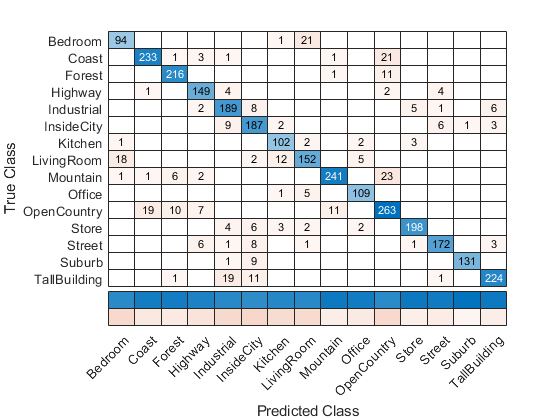

imdsTrain = imageDatastore('sceneData/sceneData/train','IncludeSubfolders',true,'LabelSource','foldernames');
imdsTest = imageDatastore('sceneData/sceneData/test','IncludeSubfolders',true,'LabelSource','foldernames');
net = resnet18;
inputSize = net.Layers(1).InputSize;
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain,'ColorPreprocessing','gray2rgb');
augimdsTest = augmentedImageDatastore(inputSize(1:2),imdsTest,'ColorPreprocessing','gray2rgb');
layer = 'pool5';
featuresTrain = activations(net,augimdsTrain,layer,'OutputAs','rows');
featuresTest = activations(net,augimdsTest,layer,'OutputAs','rows');
YTrain = imdsTrain.Labels;
YTest = imdsTest.Labels;
CList = categories(YTrain);
classifier = fitcecoc(featuresTrain,YTrain);
YPred = predict(classifier,featuresTest);
fscore = zeros(1,length(CList));
for i = 1:length(CList)
    TP = sum((YPred == CList(i)) & (YTest == CList(i)));
    Precision = TP / sum(YPred == CList(i));
    Recall = TP / sum(YTest == CList(i));
    fscore(:,i) = 2*((Precision*Recall)/(Precision+Recall));
end
confusion = confusionchart(YTest,YPred);
confusion.ColumnSummary = 'column-normalized';

confusion.RowSummary = 'row-normalized';
accuracy = mean(YPred == YTest)

accuracy = 0.8911

fscore

fscore =     0.8174    0.9066    0.9351    0.9058    0.8610    0.8519    0.8831    0.8172    0.9129    0.9356    0.8349    0.9384    0.9149    0.9597    0.9106


average_f_score = mean(fscore)

average_f_score = 0.8923